# ******************************************************************************

# **DYNAMIC RESPONSE DUE TO EARTHQUAKE LOADING USING**

# **CENTRAL DIFFERENCE METHOD, (CDM)**

# ******************************************************************************

#### *Code established by : **Dr. Raouf Bencharif  * 

#### *                                      e-mail : *[rbencharif@cgsdz.org](http://rbencharif@cgsdz.org)

#### *                                     Researchgate : *[https://www.researchgate.net/profile/Raouf-Bencharif](https://www.researchgate.net/profile/Raouf-Bencharif)

####                                      Google Scholar : [https://scholar.google.com/citations?user=2ps9VqIAAAAJ](https://scholar.google.com/citations?user=2ps9VqIAAAAJ)

#### *Senior Researcher, at the National Center of Applied Research in Earthquake Engineering,CGS, (*[http://www.cgs-dz.org/index.php/fr/](http://www.cgs-dz.org/index.php/fr/))              

#### *Department of structural Dynamic Testing, *[http://www.cgs-dz.org/index.php/fr/laboratoires/un-laboratoire-d-essais-dynamiques-des-structures](http://www.cgs-dz.org/index.php/fr/laboratoires/un-laboratoire-d-essais-dynamiques-des-structures)              

## 1. Introduction

Figure 1.1 shows a SDOF system, with viscous damping and external forcing in schematic form. The mass $m$, is assumed to be excited directly by an external force, $p\left(t\right)$. The system will be assumed to be in equilibrium when the applied force is zero; any compression or extrusion of the spring due to gravity, for example, is assumed to have already taken plan, and can be ignored as far as the vibration response is concerned.

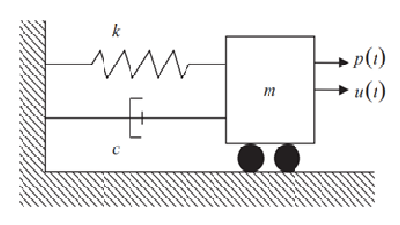

**Figure 1.1: SDOF System with Force Input**

The equation of motion governing the relative displacement  $u\left(t\right)$ of the linearly elastic structure is given by

                                                                                                                
$$m\ddot{u} +c\dot{u} +ku=p\left(t\right)$$


In the code, **Central Difference Method, (CMD)** is employed for the numerical integration of the above equation. This method is versatile as it can handle irregular loading patterns, such as earthquake ground motion, and accommodate structures whose members transition from elastic to inelastic during response.

## 2. Numerical Implementation of the CDM

Pseudo-Code of the Central Difference Method (Chopra, 2011)

     1.0 Initial calculations

            1.1   ${\ddot{u} }_0 =\frac{p_0 -c{\dot{u} }_0 -ku_0 }{m}$

            1.2    $u_{-1} =u_0 -\bigtriangleup t{\dot{u} }_0 +\frac{\left(\textrm{∆}t{\left.\right)}^2 \right.}{2}{\ddot{u} }_0$

            1.3   $\hat{k} =\frac{m}{\left(\Delta t{\left.\right)}^2 \right.}+\frac{c}{2\bigtriangleup t}$

            1.4   $a=\frac{m}{\left(\textrm{∆}t{\left.\right)}^2 \right.}-\frac{c}{2\textrm{∆}t}$

            1.5   $b=k-\frac{2m}{\left(\textrm{∆}t{\left.\right)}^2 \right.}$

     2.0 Calculation for time step $i$

            2.1   $\hat{p} =p_i -au_{i-1} -bu_i$

            2.2   $u_{i+1} =\frac{\hat{p} }{\hat{k} }$

            2.3   If required: $u_i =\frac{u_{i+1} -u_{i-1} }{2\textrm{∆}t}$;  ${\ddot{u} }_i =\frac{u_{i+1} -2u_i +u_{i-1} }{\left(\textrm{∆}t{\left.\right)}^2 \right.}$

     3.0 Repetition for the next time step

           Replace $i$ by $i+1$ and repeat steps 2.1, 2.2 and 2.3 for the next time step

If the excitation is ground acceleration ${\ddot{u} }_g \left(t\right)$replace $p_i$ by ${-m\;\ddot{u} }_{\textrm{gi}}$ where in this case ui, ˙ui,and ¨ui give response values relative to the ground.

The computed $u_i$, ${\dot{u} }_i$ , and ${\ddot{u} }_i$ give response values relative to the ground. If needed, the total velocity and acceleration can be computed readily: ${\dot{u} }_i^t ={\dot{u} }_i +{\dot{u} }_{gi}$ and ${\ddot{u} }_i^t ={\ddot{u} }_i +{\ddot{u} }_{gi}$

The central difference method will “blow up,” giving meaningless results, in the presence of numerical round-off if the time step chosen is not short enough. The specific requirement for stability is

                                                                                                                
$$\frac{\Delta t}{T_n }<\frac{1}{\pi }$$


## *3. Reference *

Chopra, Anil K. (2011), Dynamics Structures: Theory and Applications to Earthquake Engineering, 4th Edition, Prentice Hall, New Jersey.

Rajasekaran, S. (2009). *Structural dynamics of earthquake engineering: theory and application using MATHEMATICA and MATLAB*. Elsevier.

RAY, W. Clough et JOSEPH, Penzien (2003). Dynamics of structures. *Computers & Structures, Berkeley, CA, USA*.

## 4. Input motion

clear all;clc;
load KOBE.txt                % Accelerqtion time history 
g=9.8;                       % Gravity                    [m/s²]
t=KOBE(:,1);                 % Time                       [s]
Ag=KOBE(:,2)*g;              % Acceleration               [m/s²]       
dt= t(2)-t(1);               % Time interval              [s]
At=KOBE;

## 5. Plot input motion

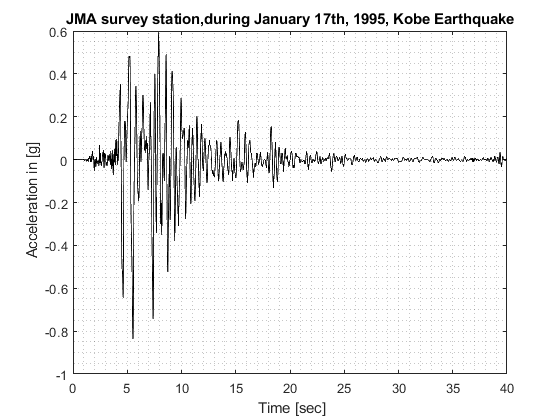

plot(t,Ag/g,'k');xlabel(' Time [sec]');
              ylabel(' Acceleration in [g]');
              title('JMA survey station,during January 17th, 1995, Kobe Earthquake');grid minor;

## 6. Characteristics of the SDOF system

m=120;                       % Mass                      [Ton]
T=0.4;                       % Period                    [seconds]
k=m*(2*pi/T)^2;              % Stiffness                 [KN]
zeta =0.05;                  % Critical damping Ratio    [%]
wn=sqrt(k/m);                % Circular frequency        [rad/s]
c=2*m*wn*zeta;               % Damping value             [KN s/m]

## 7. Check of stability condition

if dt/T<1/pi
    display('The solution is stable')
else
    display('The solution is not stable')
end

The solution is stable


## 8. Vector force  

P=-m*Ag;                      % Load vector              [KN]

## 9. Initial calculations


u(1)=0;
v(1)=0;


## 10. Calculation process

an(1)=(P(1)-c*v(1)-k*u(1))/m;
up=u(1)-dt*v(1)+dt*dt*an(1)/2;
kh=m/(dt*dt)+c/(2.0*dt);
a=m/(dt*dt)-c/(2.0*dt);
b=k-2.0*m/(dt*dt);
f(1)=P(1)-a*up-b*u(1);
u(2)=f(1)/kh;

for i=2:length(P)-1
    f(i)=P(i)-a*u(i-1)-b*u(i);
    u(i+1)=f(i)/kh;
end

v(1)=(u(2)-up)/(2.0*dt);

for m=2:length(P)-1
    v(m)=(u(m+1)-u(m-1))/(2.0*dt);
    an(m)=(u(m+1)-2.0*u(m)+u(m-1))/(dt*dt);
end

## 11. Plot responses

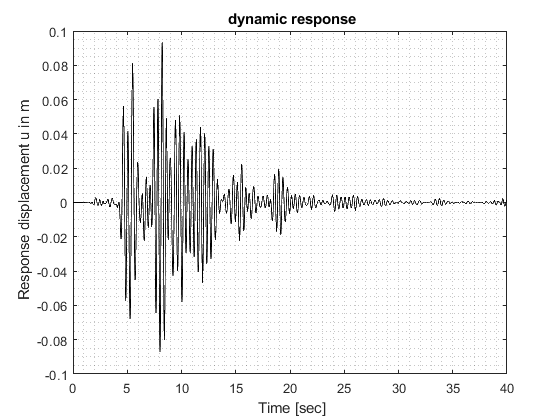



plot(t,u,'k');xlabel(' Time [sec]');
              ylabel(' Response displacement u in m');
              title(' dynamic response');grid minor;

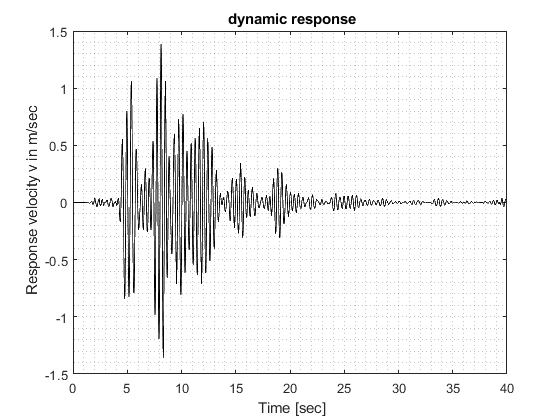


plot(t(1:end-1),v,'k');xlabel(' Time [sec]');
              ylabel(' Response velocity v in m/sec');
              title(' dynamic response');grid minor;